# 使用Frenet参考路径的高速公路轨迹规划

此示例演示如何在高速公路驾驶场景中规划局部轨迹。此示例使用参考路径和动态障碍物列表来为自车生成替代轨迹。自车在来自于drivingScenario对象提供的驾驶场景中定义的交通中导航。车辆根据cost、可行性和无碰撞运动在自适应巡航控制、车道变换和车辆跟随操作之间交替。

[image: 2020-06-19_17-27-45.gif]

## 加载驾驶场景

首先加载提供的drivingScenario对象，该对象定义当前工作区中的车辆和道路属性。该场景是使用[**Driving Scenario Designer**](docid:driving_ref#mw_07e6310f-b9c9-4f4c-b2f9-51e31d407766) app生成的，并导出到MATLAB函数drivingScenarioTrafficExample。有关更多信息，请参阅[Create Driving Scenario Variations Programmatically](docid:driving_ug#mw_2282a3a3-f2b9-4a03-9638-ae7d5b20f8d8)。

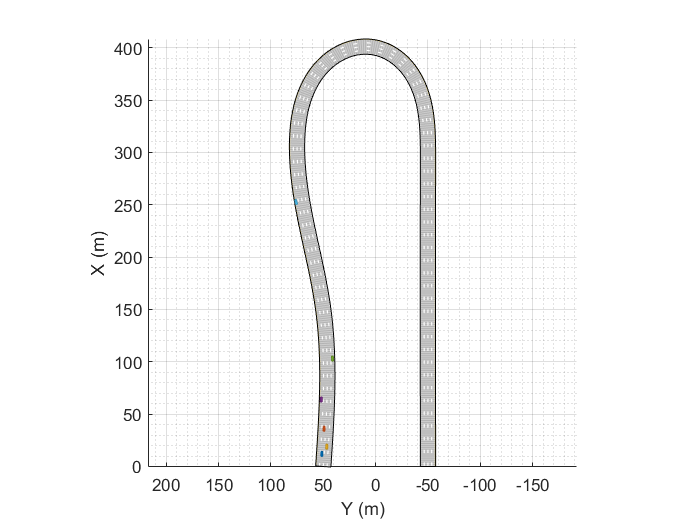

clc,clear
scenario = drivingScenarioTrafficExample;
% Default car properties
carLen   = 4.7; % in meters
carWidth = 1.8; % in meters
rearAxleRatio = .25;

% Define road dimensions
laneWidth   = carWidth*2; % in meters

plot(scenario);

## 构造参考路径

本示例中的所有局部规划都是针对由referencePathFrenet对象表示的参考路径进行的。该对象可以返回沿着参考路径给定长度的曲线状态，找到沿着路径到某个全局xy位置的最近点，并便于全局参考系和Frenet参考系之间的坐标转换。

对于本例，参考路径被视为四车道公路的中心，路径点与所提供的drivingScenario对象中定义的道路匹配。

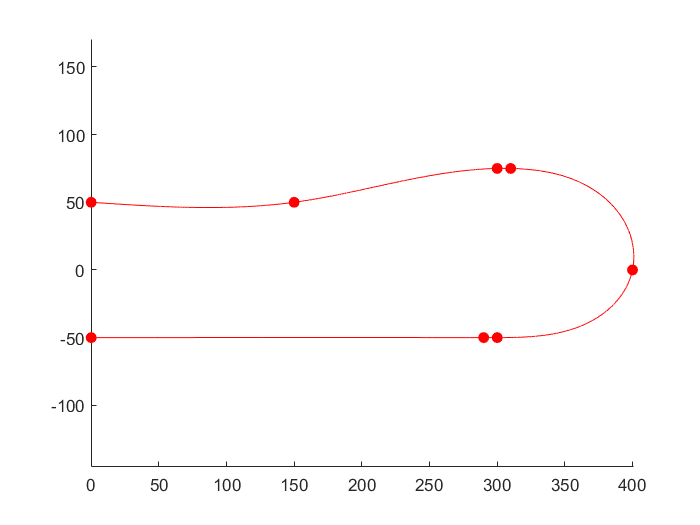

waypoints = [0 50; 150 50; 300 75; 310 75; 400 0; 300 -50; 290 -50; 0 -50]; % in meters
refPath = referencePathFrenet(waypoints);
ax = show(refPath);
axis(ax,'equal');

## 构建轨迹发生器

对于局部规划器，目标通常是对朝着最终目标移动的各种可能运动进行采样，同时满足当前的运动学和动态条件。trajectoryGeneratorFrenet对象通过使用4阶或5阶多项式轨迹将初始状态和一组终止状态连接来实现这一点。在Frenet坐标系中定义了初始和终止状态，每个多项式解都满足横向和纵向位置、速度和加速度边界条件，同时最大限度地减少jerk。

终端状态通常使用自定义行为计算。这些行为利用了在局部环境中发现的信息，例如车道信息、速度限制以及自车附近参与者的当前和未来预测。

使用参考路径构造一个trajectoryGeneratorFrenet对象。

connector = trajectoryGeneratorFrenet(refPath);

## 构造动态碰撞检查器

[`dynamicCapsuleList`](docid:nav_ref#mw_7adae6fc-28a4-49cf-9120-4a0b7c6bce23)`对象是一种数据结构，表示动态环境在一组离散的时间步长上的状态。然后可以使用该环境有效地验证自车的多个潜在轨迹。场景中的每个对象都表示为：`

- 唯一整数值标识符。

- 用于有效碰撞检查的胶囊几何体的属性。

- SE2状态序列，其中每个状态代表一个离散的时间快照。

`在此示例中，trajectoryGeneratorFrenet对象生成的轨迹发生在某个时间跨度内，称为时间范围。为确保碰撞检查涵盖所有可能的轨迹，dynamicCapsuleList对象应包含跨越最大期望时间范围的所有参与者的预测轨迹。`

capList = dynamicCapsuleList;

使用给定的参数为自车创建几何结构

egoID = 1;
[egoID, egoGeom] = egoGeometry(capList,egoID);

egoGeom.Geometry.Length = carLen; % in meters
egoGeom.Geometry.Radius = carWidth/2; % in meters
egoGeom.Geometry.FixedTransform(1,end) = -carLen*rearAxleRatio; % in meters

将自车添加到动态胶囊列表中。

updateEgoGeometry(capList,egoID,egoGeom);

将drivingScenario添加到dynamicCapsuleList对象。几何在此处设置，状态在规划循环期间定义。你将看到dynamicCapsuleList现在包含一个自车和五个障碍物。

actorID = (1:5)';
actorGeom = repelem(egoGeom,5,1);
updateObstacleGeometry(capList,actorID,actorGeom)

ans =   dynamicCapsuleList - 属性:

     MaxNumSteps: 31
          EgoIDs: 1
     ObstacleIDs: [5×1 double]
    NumObstacles: 5
         NumEgos: 1


## 通过交通规划自适应路线

规划工具支持一种局部规划策略，即在选择最优轨迹之前，根据当前和可预见的环境状态对一组局部轨迹进行采样。模拟循环被组织成以下几个部分：

- 推进地面真实场景

- 生成终端状态

- 评估终端状态的成本

- 生成轨迹和检查运动学的可行性

- 检查碰撞轨迹并选择最优轨迹

- 显示采样的轨迹和动画场景

点击每个部分的标题以导航到模拟循环中的相关代码

### 推进地面真实场景

在动态环境中进行规划时，通常需要估计环境的状态或预测其在将来的状态。为简单起见，本例使用drivingScenario作为每个参与者在规划范围内的轨迹的真实来源。要测试自定义预测算法，您可以使用自定义代码替换或修改exampleHelperRetrieveActorGroundTruth函数。

### 生成终端状态

自动驾驶的一个共同目标是确保规划的轨迹不仅是可行的，而且是自然的。典型的公路驾驶包括车道保持、限速、变道、车速适应交通等要素。每个自定义行为可能需要不同的环境信息。这个例子演示了如何生成实现三种行为的终端状态：巡航控制、换道和跟随前车。

#### 巡航控制

exampleHelperBasicCruiseControl函数生成执行巡航控制行为的终端状态。该函数利用自车的横向速度和时间范围来预测自车在未来N秒内的期望车道。计算车道中心成为终端状态的横向偏差，并将横向速度和加速度设为零。

对于纵向边界条件，终端速度设为道路限速，终端加速度设为零。纵向位置不受限，指定为NaN。因此trajectoryGeneratorFrenet可以使用一个较低的四阶多项式来解决纵向边界问题，从而得到一个在给定时间范围内与道路速度平稳匹配的轨迹：


$$cruiseControlState=\left\lbrack \textrm{NaN}\;{\dot{s} }_{des} \ 0\ l_{expLane} \ 0\ 0\right\rbrack$$


#### 换道

exampleHelperBasicLaneChange函数生成将车辆从当前车道转换到相邻车道的终端状态。该函数首先确定自车当前的车道，然后检查左右车道是否存在。对于每条已有车道，终端状态的定义与巡航控制行为相同，只是终端速度设置为当前速度而不是道路限速。


$$laneChangeState={\left[\textrm{NaN}\;\;{\dot{s} }_{cur} \;\ 0\ l_{desLane} \ 0\ 0\right]}$$


#### 跟随前车

exampleHelperBasicLeadVehicleFollow函数生成试图跟踪前方车辆的本车终端状态。该函数首先确定自车的当前车道。对于每个给定的timeHorizon，函数预测每个行动者的未来状态，找到与当前车辆占据同一车道的所有actors，并确定哪一个是最近的前车（如果没有发现前车，函数不返回任何东西）。

通过取前车的位置和速度，将末端纵向位置减小一定的安全距离，计算自车的终端状态：


$$closestLeadVehicl\textrm{eState}=\left\lbrack s_{lead} \ {\dot{s} }_{lead} \ 0\ l_{lead} \ {\dot{l} }_{lead} \ 0\right\rbrack$$



$$\textrm{followState}=\left\lbrack \left(s_{lead} -d_{\textrm{safety}} \right)\ {\dot{s} }_{lead} \ 0\ l_{lead} \ {\dot{l} }_{lead} \ 0\right\rbrack$$


### 评估终端状态的成本

在生成终端状态之后，可以评估它们的代价。轨迹评估和对潜在解决方案进行优先排序的方法是非常主观的。为简单起见，exampleHelperEvaluateTSCost函数将成本定义为三个加权总和的组合。

- ** 横向偏差成本(**$C_{latDev}$**) **— 正权重，惩罚偏离车道中心的状态的.


$$C_{latDev} =w_{\Delta L} *\Delta \mathrm{L}$$



$$\Delta L={\textrm{argmin}}_i \left(\left|L_{\textrm{termState}} \;-L_{{\textrm{lane}}_i } \right|\right)$$


（问题：为什么是取最小的偏差，按照我的理解不应该取最大的偏差吗？？？）

- **时间成本 (**$C_{time}$**) **—负权重，优先考虑发生在较长时间间隔内的运动，从而产生更平滑的轨迹.


$$C_{time} =w_{\Delta t} *\Delta t$$


- **终端速度成本 (**$C_{speed}$**) **— 正权重，优先考虑保持速度限制的运动，从而减少动态机动.


$$C_{speed} =w_{\Delta v} *\Delta v$$


### 生成轨迹和检查运动学的可行性

除了具有最低成本的终端状态外，最佳轨迹通常还必须满足与运动可行性和乘坐舒适性相关的额外约束。轨迹约束是实现所需乘坐质量的一种方式，但这样做的代价是降低了行驶范围。

在此示例中，exampleHelperEvaluateTrajectory函数验证每个轨迹约束是否满足以下约束：

- `最大加速度`: 整个轨迹的绝对加速度必须低于指定值。较小的值会降低驾驶侵略性并消除运动学上不可行的轨迹。此限制可能会删除车辆原本可以执行的操作.

- `最大曲率`: 整个轨迹允许的最小转弯半径。与最大加速度一样，降低此值可带来更顺畅的驾驶体验，但可能会删除其他可行的轨迹.

- `最小速度`:此示例通过设置最小速度将自车限制为仅向前运动。在高速公路驾驶场景中需要此限制，并消除过度约束或条件不佳的边界值的轨迹.

### 检查碰撞轨迹并选择最优轨迹

规划过程的最后一步是选择最佳轨迹，同时也能满足无碰撞路径。碰撞检测通常被推迟到最后，因为它是一项资源消耗比较大的操作，因此通过首先评估成本和分析约束，可以删除无效的轨迹。然后可以以最佳排序检查剩余轨迹的碰撞，直到找到无碰撞路径或评估所有轨迹。

## 定义仿真器和规划参数

 本节定义了运行模拟器所需的属性以及规划器和行为程序使用的参数。例如scenario的属性，`SampleTime and` `connector`。时间求解是同步的，以便真值actor轨迹和规划的自车轨迹在相同的步长时间发生。类似地，选择replanRate,timeHorizons和maxHorizon，使它们是模拟速率的整数倍。

如上一节所述，选择权重和约束以在遵守道路规则的同时促进平稳的驾驶轨迹。

最后，定义speedLimit和safetyGap参数，用于为规划器生成终端状态。

% 模拟器的更新率匹配同步为轨迹生成器的更新率
% 离散间隔.
scenario.SampleTime = connector.TimeResolution; % in seconds

% 定义规划参数.
replanRate = 10; % Hz

% Define the time intervals between current and planned states.
% 定义规划的时间点吧？
timeHorizons = 1:3; % in seconds
maxHorizon = max(timeHorizons); % in seconds

% Define cost parameters.
latDevWeight    =  1;
timeWeight      = -1;
speedWeight     =  1;

% 拒绝违反以下约束的轨迹.
maxAcceleration =  15; % in meters/second^2
maxCurvature    =   1; % 1/meters, or radians/meter
minVelocity     =   0; % in meters/second

% 期望的速度设定值，用于巡航控制和评估轨迹成本。
speedLimit = 11; % in meters/second

% Minimum distance the planner should target for following behavior.
% 规划器应以下列行为作为目标的最小距离，什么意思？？？
safetyGap = 10; % in meters


## 初始化仿真器

初始化仿真器并创建[`chasePlot`](docid:driving_ref#bvna0wv)`查看器`

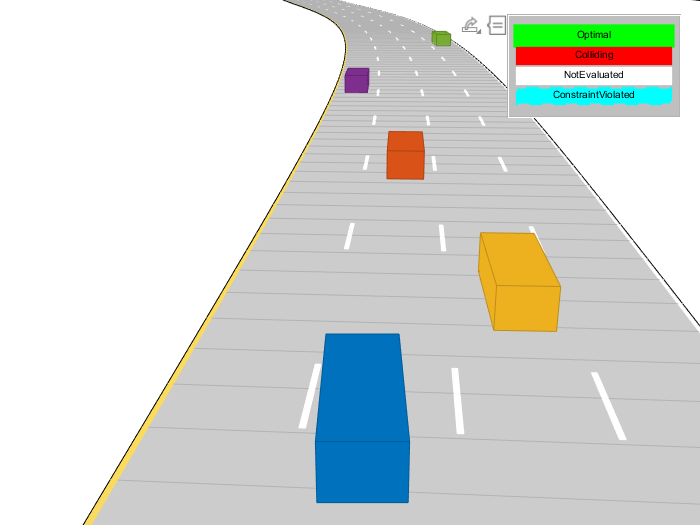

[scenarioViewer,futureTrajectory,actorID,actorPoses,egoID,egoPoses,stepPerUpdate,egoState,isRunning,lineHandles] = ...
    exampleHelperInitializeSimulator(scenario,capList,refPath,laneWidth,replanRate,carLen);

## 运行驾驶模拟

tic
while isRunning
    % 检索actor车辆的当前状态及其在规划范围内的轨迹.
    [curActorState,futureTrajectory,isRunning] = ...
        exampleHelperRetrieveActorGroundTruth(scenario,futureTrajectory,replanRate,maxHorizon);

    % 生成巡航控制状态.为什么巡航控制要根据当前状态预测未来采样时间终点时本车所处的车道呢？？？
    % 到这个车道的时候横向加速度和横向速度都为0，可能也是为了根据当前的车辆状态能平稳的过渡到该车道中心吧
    [termStatesCC,timesCC] = exampleHelperBasicCruiseControl(...
        refPath,laneWidth,egoState,speedLimit,timeHorizons);
    
    % 生成换道状态.根据本车所处的车道选择左右两个车道作为目标车道，计算出横向L的目标距离，换道末状态的横向速度和加速度都应当为0，纵向不指定末状态位置，指定纵向加速度为0，纵向速度和换道起始点相同
    [termStatesLC,timesLC] = exampleHelperBasicLaneChange(...
        refPath,laneWidth,egoState,timeHorizons);
    
    % 生成车辆跟随状态.计算自车和障碍车actors所处的车道，找出和本车最近的在径前车，目标状态是保持在在径前车后的安全距离位置处，纵向终端速度和前车保持一直，横向终端位置和速度和前车保持一致
    [termStatesF,timesF] = exampleHelperBasicLeadVehicleFollow(...
        refPath,laneWidth,safetyGap,egoState,curActorState,timeHorizons);

    % 结合终端状态和时间
    allTS = [termStatesCC; termStatesLC; termStatesF];
    allDT = [timesCC; timesLC; timesF];
    numTS = [numel(timesCC); numel(timesLC); numel(timesF)];
    
    % 评估所有终端状态的代价
    costTS = exampleHelperEvaluateTSCost(allTS,allDT,laneWidth,speedLimit,...
        speedWeight, latDevWeight, timeWeight);

    % 生成轨迹.生成起始点连接终端点曲线的按时间间隔0.1s得到的Frenet坐标系下的[S ds ddS L dL ddL]和笛卡尔坐标系下的[x, y,theta, kappa, v, a]
    egoFrenetState = global2frenet(refPath,egoState);
    [frenetTraj,globalTraj] = connect(connector,egoFrenetState,allTS,allDT);

    % 删除违反约束的轨迹，检查加速度，曲率，速度限制，若任何一个时间点的状态不满足都删除该条轨迹
    isValid = exampleHelperEvaluateTrajectory(globalTraj,maxAcceleration,maxCurvature,minVelocity);

    % 使用场景中所有actors的预测轨迹更新碰撞检查器
    for i = 1:numel(actorPoses)
        actorPoses(i).States = futureTrajectory(i).Trajectory(:,1:3);
    end
    updateObstaclePose(capList,actorID,actorPoses);
    
    % Determine evaluation order.
    % 确定评估顺序
    [cost, idx] = sort(costTS);
    optimalTrajectory = [];
    
    trajectoryEvaluation = nan(numel(isValid),1);

    % 从最低成本的轨迹开始检查是否由碰撞
    for i = 1:numel(idx)
        if isValid(idx(i))
            % Update capsule list with the ego object's candidate trajectory.
            % 用自车对象的候选轨迹更新胶囊列表？？？
            egoPoses.States = globalTraj(idx(i)).Trajectory(:,1:3);
            updateEgoPose(capList,egoID,egoPoses);
            
            % Check for collisions.
            isColliding = checkCollision(capList);
            
            if all(~isColliding)
                % If no collisions are found, this is the optimal.
                % trajectory.
                trajectoryEvaluation(idx(i)) = 1;
                optimalTrajectory = globalTraj(idx(i)).Trajectory;
                break;
            else
                trajectoryEvaluation(idx(i)) = 0;
            end
        end
    end

    % Display the sampled trajectories.
    lineHandles = exampleHelperVisualizeScene(lineHandles,globalTraj,isValid,trajectoryEvaluation);
    
    hold on;
    show(capList,'TimeStep',1:capList.MaxNumSteps,'FastUpdate',1);
    hold off;
    
    if isempty(optimalTrajectory)
        % All trajectories either violated a constraint or resulted in collision.
        %
        %   If planning failed immediately, revisit the simulator, planner,
        %   and behavior properties.
        %
        %   If the planner failed midway through a simulation, additional
        %   behaviors can be introduced to handle more complicated planning conditions.
        error('No valid trajectory has been found.');
    else
        % Visualize the scene between replanning.
        for i = (2+(0:(stepPerUpdate-1)))
            % Approximate realtime visualization.
            dt = toc;
            if scenario.SampleTime-dt > 0
                pause(scenario.SampleTime-dt);
            end
            
            egoState = optimalTrajectory(i,:);
            scenarioViewer.Actors(1).Position(1:2) = egoState(1:2);
            scenarioViewer.Actors(1).Velocity(1:2) = [cos(egoState(3)) sin(egoState(3))]*egoState(5);
            scenarioViewer.Actors(1).Yaw = egoState(3)*180/pi;
            scenarioViewer.Actors(1).AngularVelocity(3) = egoState(4)*egoState(5);
            
            % Update capsule visualization.
            hold on;
            show(capList,'TimeStep',i:capList.MaxNumSteps,'FastUpdate',1);
            hold off;
            
            % Update driving scenario.
            advance(scenarioViewer);
            ax = gca;
            ax.ZLim = [-100 100];
            tic;
        end
    end
end